%% Multi-Input NLMS for Stereo Adaptive Noise Cancellation
clear; close all; clc;

%% === 1. Load Data ===
load('Hw2a.mat');  % Sin_a, Sn_ref_a, fs
[N, M] = size(Sin_a);  % M = 2 channels

%% === 2. Parameters ===
filter_order = 512;      % filter length
mu = 0.01;               % step size (normalized)
delta = 1e-6;           % stability constant
max_samples = N;        % use full signal

%% === 3. Initialization ===
Sin_est = zeros(N, M);                    % estimated output
W = zeros(filter_order, M, M);            % W(filt_idx, ref_channel, target_channel)

%% === 4. Adaptive Filtering: Multi-Input NLMS
for ch = 1:M  % ch = target output channel (1 or 2)
    d = Sin_a(:, ch);                     % noisy signal for channel ch
    e = zeros(max_samples, 1);           % error / estimated clean signal
    y = zeros(max_samples, 1);           % predicted noise

    for n = filter_order:max_samples
        % Build input vectors for both references
        x1 = Sn_ref_a(n:-1:n-filter_order+1, 1);  % Reference 1
        x2 = Sn_ref_a(n:-1:n-filter_order+1, 2);  % Reference 2

        % Predicted noise
        y(n) = W(:,1,ch)' * x1 + W(:,2,ch)' * x2;

        % Error (desired - predicted)
        e(n) = d(n) - y(n);

        % Normalize input energy
        norm_factor = (x1'*x1 + x2'*x2 + delta);

        % Update weights for both references
        W(:,1,ch) = W(:,1,ch) + (mu * e(n) * x1) / norm_factor;
        W(:,2,ch) = W(:,2,ch) + (mu * e(n) * x2) / norm_factor;
    end

    Sin_est(:, ch) = e;  % save denoised signal
end

%% === 5. Play and Visualize Results ===
disp('▶ Playing denoised stereo audio...');

▶ Playing denoised stereo audio...


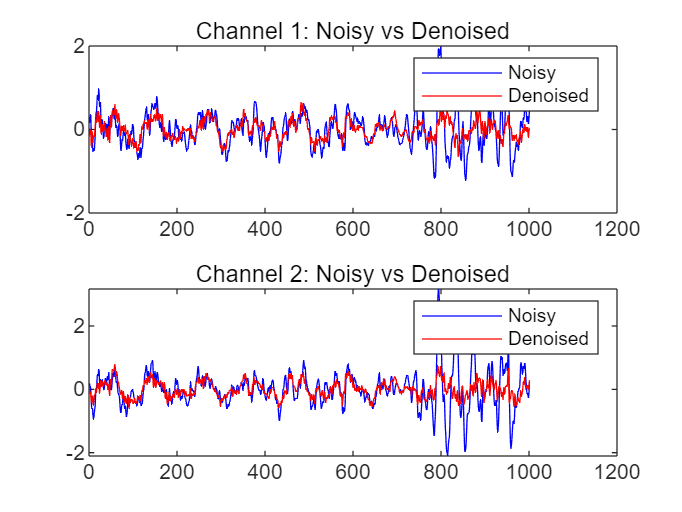

sound(Sin_est, fs);
pause(N/fs + 1);

%% === 6. Time Domain Comparison ===
figure;
for ch = 1:M
    subplot(M, 1, ch);
    plot(Sin_a(N-111000:N-110000, ch), 'b'); hold on;
    plot(Sin_est(N-111000:N-110000, ch), 'r');
    title(['Channel ', num2str(ch), ': Noisy vs Denoised']);
    legend('Noisy', 'Denoised');
end

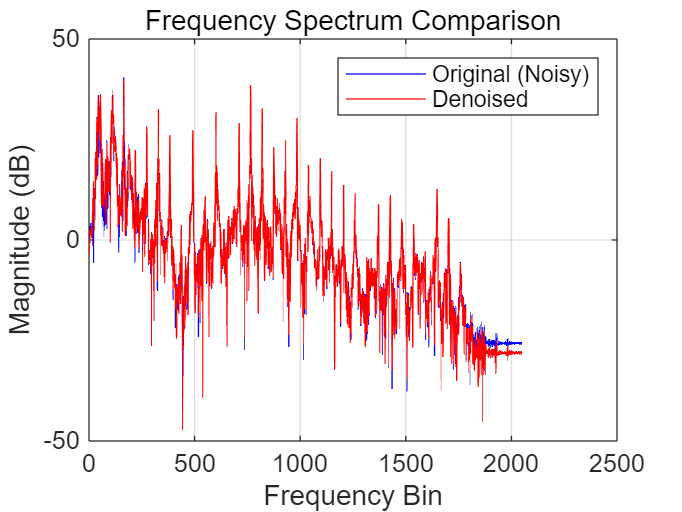


%% === 7. Frequency Spectrum Comparison ===
N_fft = 4096;
S = fft(Sin_a(:,1), N_fft);
E = fft(Sin_est(:,1), N_fft);

figure;
plot(20*log10(abs(S(1:N_fft/2))), 'b'); hold on;
plot(20*log10(abs(E(1:N_fft/2))), 'r');
legend('Original (Noisy)', 'Denoised');
title('Frequency Spectrum Comparison');
xlabel('Frequency Bin');
ylabel('Magnitude (dB)');
grid on;